% Transfer Function Definition
s = tf('s');
J = 0.0013; % kg\*m^2
b = 3.2848e-5; % N\*m\*s
K = 0.318; % Nm/A
R = 3; % Ohms
L = 380e-6; % Henrys
P_motor = K / ((J*s + b) * (L*s + R) + K^2);

% Controller
Ein = 12;
Ea = 6;
D = Ea/Ein;
p_conv = D;
plant = p_conv * P_motor;


Kp = 0.4; 
Ki = 10;
Kd = 0;
C = pid(Kp, Ki, Kd);

sys_cl = feedback(C*plant,1)

sys_cl =
 
                0.0636 s + 1.59
  -------------------------------------------
  4.94e-07 s^3 + 0.0039 s^2 + 0.1648 s + 1.59
 
Continuous-time transfer function.
Model Properties



Ts = 0.001; % Specify the desired sampling time

C_d = c2d(C,Ts,'tustin')

plant_d = c2d(sys_cl, Ts, 'tustin')

plant_d =
 
  0.006477 z^3 + 0.006637 z^2 - 0.006157 z - 0.006317
  ---------------------------------------------------
          z^3 - 1.364 z^2 - 0.2046 z + 0.5693
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties


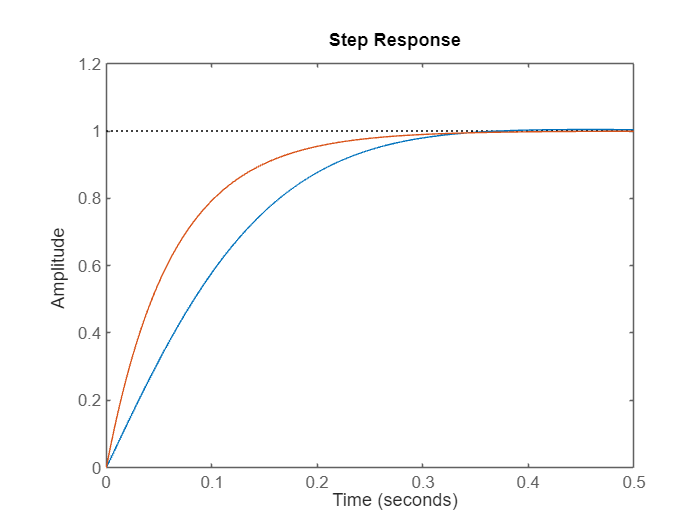


sys_cl_d = feedback(C_d*plant_d,1);

t = 0:Ts:0.5;
step(sys_cl_d, t)
hold on
step(sys_cl,t)
hold off


controlSystemDesigner('rlocus', plant_d)

stepinfo(plant_d)

ans = struct with fields:
         RiseTime: 0.1410
    TransientTime: 0.2550
     SettlingTime: 0.2550
      SettlingMin: 0.9011
      SettlingMax: 0.9998
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9998
         PeakTime: 0.5490


% Sampling Time
Ts = 0.001; % Specify the desired sampling time

% Convert continuous-time plant to discrete-time
plant_d = c2d(plant, Ts, 'zoh');

% PI Controller
Kp = 0.4;
Ki = 10;
Kd = 0;
C = pid(Kp, Ki, Kd);

% Convert continuous-time PID controller to discrete-time
C_d = c2d(C, Ts, 'tustin');

% Closed-loop system with discrete-time models
sys_cl_d = feedback(C_d * plant_d, 1);

% Simulate and plot the step response
t = 0:Ts:0.5;
step(sys_cl_d, t)

% Display step response information
info = stepinfo(sys_cl_d)
disp(plant_d);